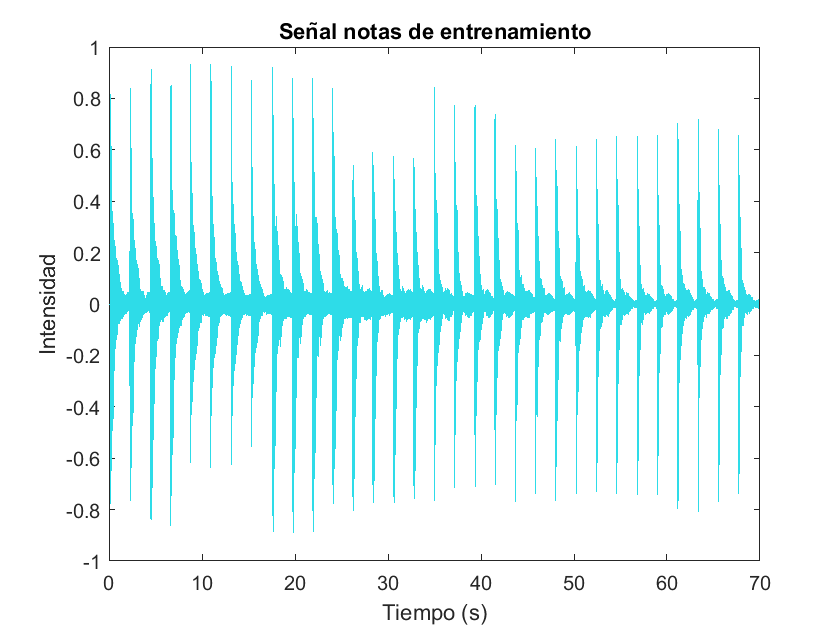

%Leemos la señal
[signal, Fs] = audioread("training_notes_2.m4a");
%Nos quedamos unicamente con el primer canal
signal = signal(:,1);
deltaT = 1/Fs;
%Construimos el arreglo de tiempos
tArray = (0:length(signal) - 1)*deltaT;
%Vamos a graficar la señal
figure()
plot(tArray, signal, 'Color', '#2edce8')
title("Señal notas de entrenamiento")
xlabel("Tiempo (s)")
ylabel("Intensidad")

### Cortes de las distintas notas

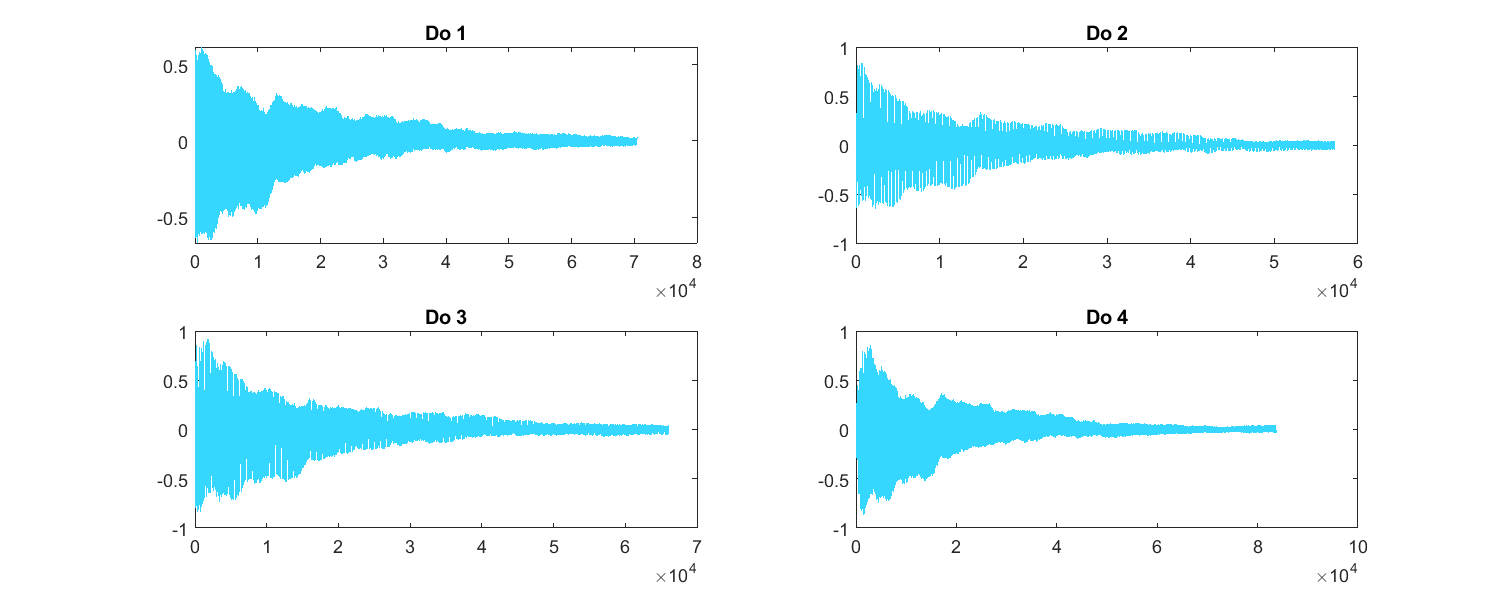

%Cortes de Do
cCut1 = cutWithTime(tArray, signal, 0.2, 1.8);
cCut2 = cutWithTime(tArray, signal, 2.3, 3.6);
cCut3 = cutWithTime(tArray, signal, 4.5, 6);
cCut4 = cutWithTime(tArray, signal, 6.6, 8.5);
f = figure();
f.Position = [100 100 1000 400];
subplot(2,2,1)
plot(cCut1, "Color", "#36d7ff")
title("Do 1")
subplot(2,2,2)
plot(cCut2,"Color" ,"#36d7ff")
title("Do 2")
subplot(2,2,3)
plot(cCut3, "Color", "#36d7ff")
title("Do 3")
subplot(2,2,4)
plot(cCut4, "Color", "#36d7ff")
title("Do 4")

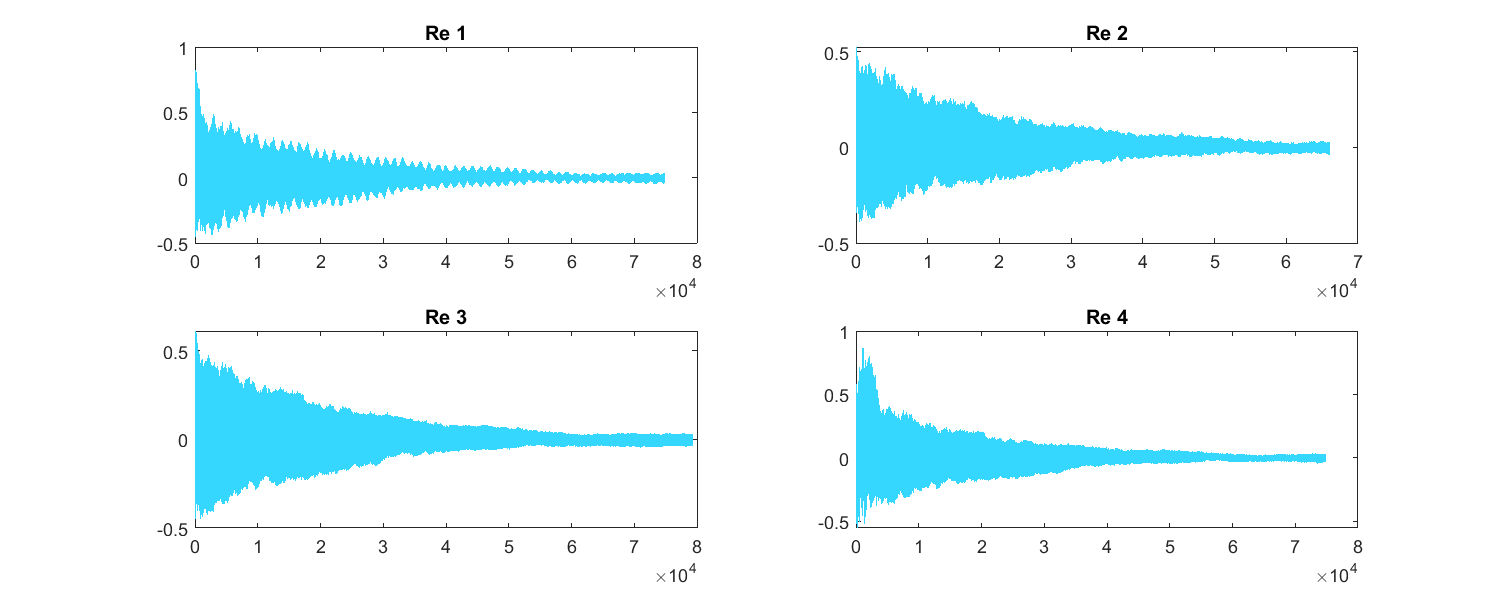

%Cortes de Re
dCut1 = cutWithTime(tArray, signal, 8.8, 10.5);
dCut2 = cutWithTime(tArray, signal, 11, 12.5);
dCut3 = cutWithTime(tArray, signal, 13.2, 15);
dCut4 = cutWithTime(tArray, signal, 15.3,17);
f = figure();
f.Position = [100 100 1000 400];
subplot(2,2,1)
plot(dCut1, "Color", "#36d7ff")
title("Re 1")
subplot(2,2,2)
plot(dCut2, "Color", "#36d7ff")
title("Re 2")
subplot(2,2,3)
plot(dCut3, "Color", "#36d7ff")
title("Re 3")
subplot(2,2,4)
plot(dCut4, "Color", "#36d7ff")
title("Re 4")

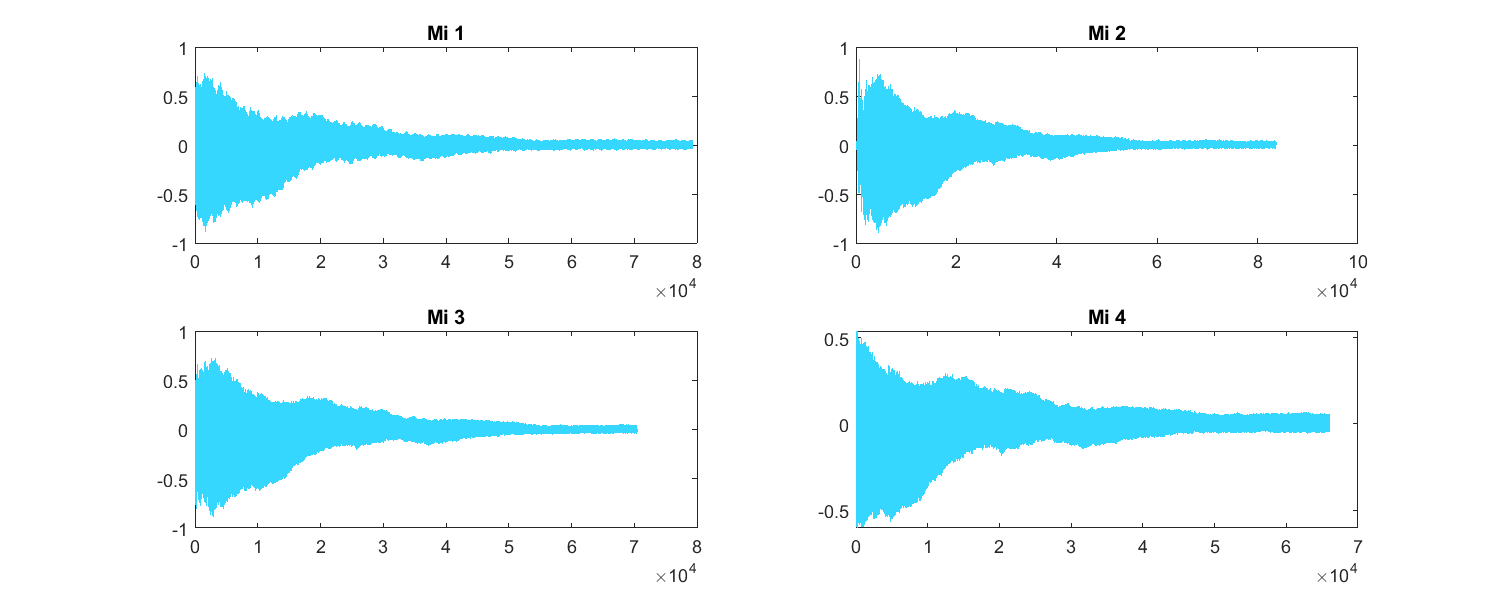

%Cortes de Mi

eCut1 = cutWithTime(tArray, signal, 17.6,19.4);
eCut2 = cutWithTime(tArray, signal, 19.7, 21.6);
eCut3 = cutWithTime(tArray, signal,21.9 , 23.5);
eCut4 = cutWithTime(tArray, signal,24.2,25.7);
f = figure();
f.Position = [100 100 1000 400];
subplot(2,2,1)
plot(eCut1, "Color", "#36d7ff")
title("Mi 1")
subplot(2,2,2)
plot(eCut2, "Color", "#36d7ff")
title("Mi 2")
subplot(2,2,3)
plot(eCut3, "Color", "#36d7ff")
title("Mi 3")
subplot(2,2,4)
plot(eCut4, "Color", "#36d7ff")
title("Mi 4")

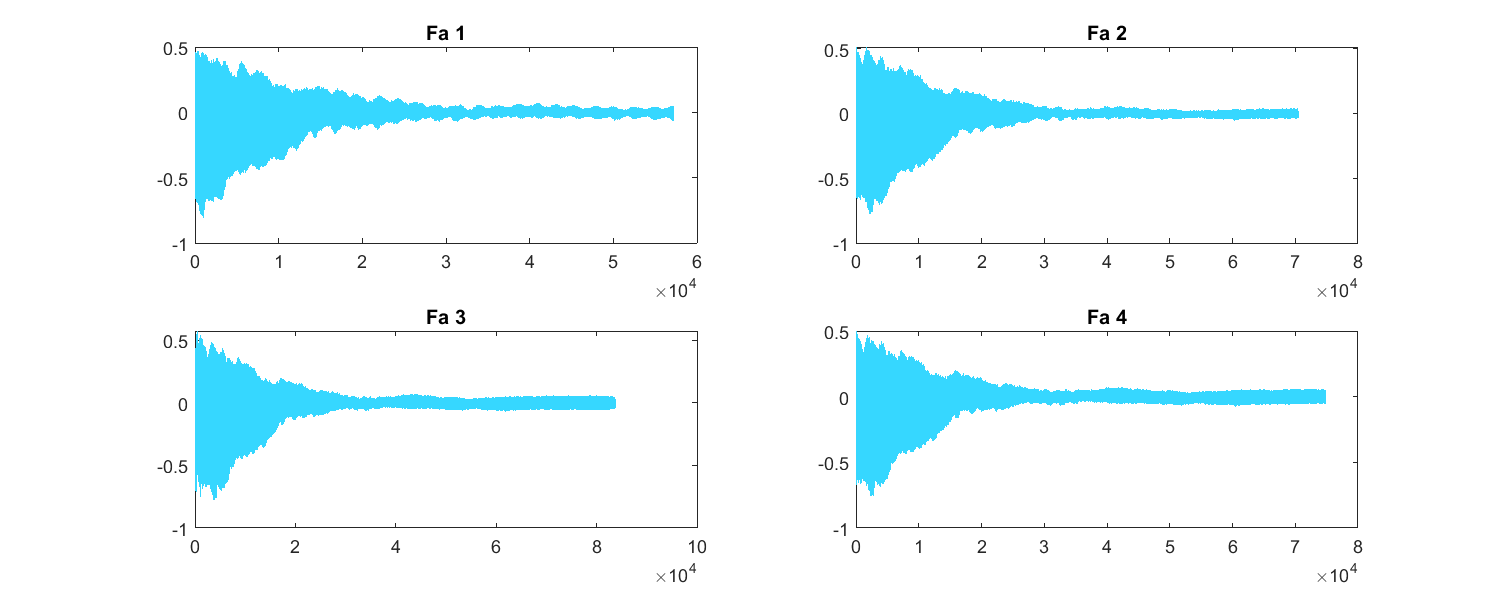

%Cortes de Fa
fCut1 = cutWithTime(tArray, signal, 26.3, 27.6);
fCut2 = cutWithTime(tArray, signal, 28.4, 30);
fCut3 = cutWithTime(tArray, signal, 30.6, 32.5);
fCut4 = cutWithTime(tArray, signal,32.8, 34.5);
f = figure();
f.Position = [100 100 1000 400];
subplot(2,2,1)
plot(fCut1, "Color", "#36d7ff")
title("Fa 1")
subplot(2,2,2)
plot(fCut2, "Color", "#36d7ff")
title("Fa 2")
subplot(2,2,3)
plot(fCut3, "Color", "#36d7ff")
title("Fa 3")
subplot(2,2,4)
plot(fCut4, "Color", "#36d7ff")
title("Fa 4")

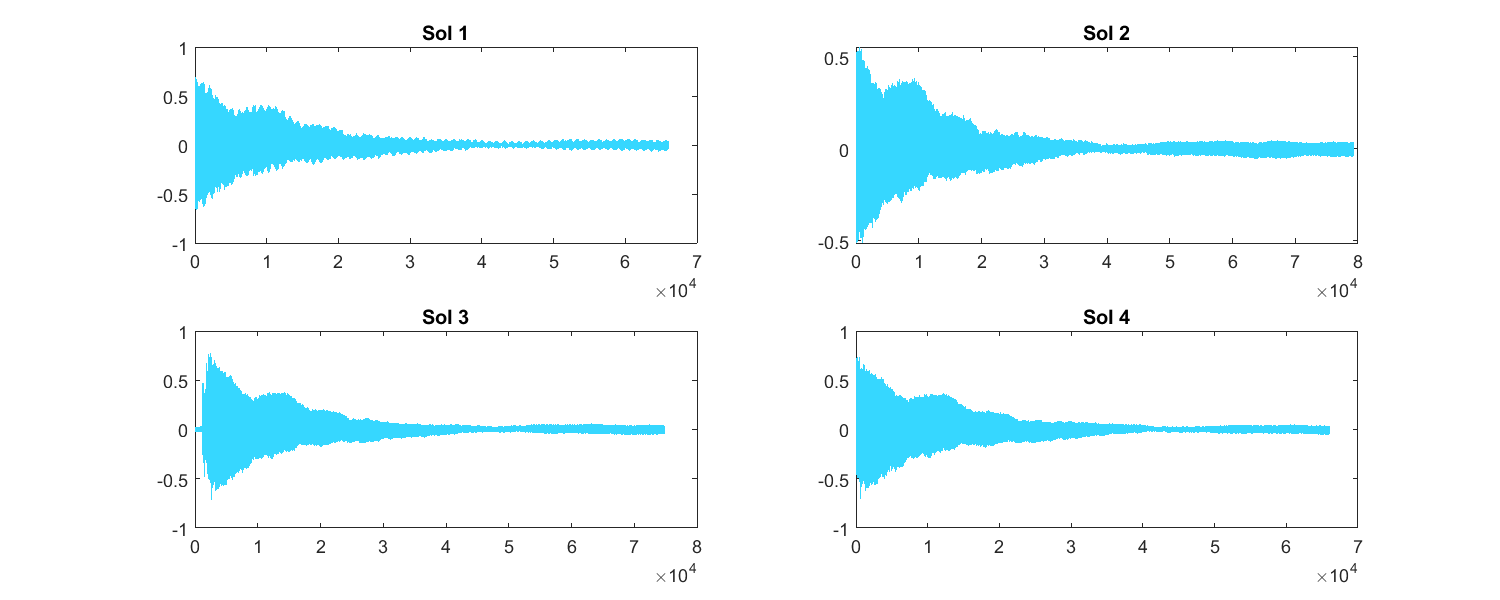

%Cortes de Sol
gCut1 = cutWithTime(tArray, signal, 35, 36.5);
gCut2 = cutWithTime(tArray, signal, 37.2, 39);
gCut3 = cutWithTime(tArray, signal, 39.3, 41);
gCut4 = cutWithTime(tArray, signal, 41.5, 43);

f = figure();
f.Position = [100 100 1000 400];
subplot(2,2,1)
plot(gCut1, "Color", "#36d7ff")
title("Sol 1")
subplot(2,2,2)  
plot(gCut2,"Color" ,"#36d7ff")
title("Sol 2")
subplot(2,2,3)  
plot(gCut3,"Color" ,"#36d7ff")
title("Sol 3")
subplot(2,2,4)  
plot(gCut4,"Color" ,"#36d7ff")
title("Sol 4")

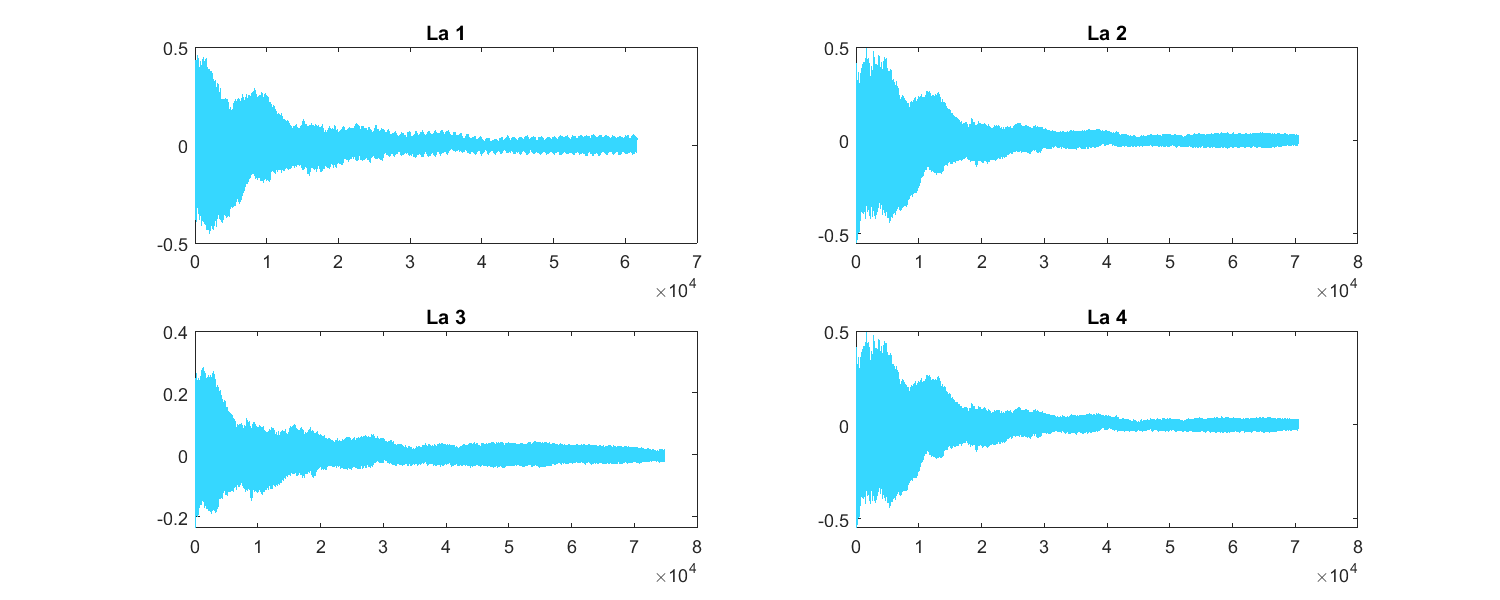

%Cortes de La 
aCut1 = cutWithTime(tArray, signal, 43.8, 45.2);
aCut2 = cutWithTime(tArray, signal, 45.9, 47.5);
aCut3 = cutWithTime(tArray, signal, 48.3, 50);
aCut4 = cutWithTime(tArray, signal, 50.4, 52);
f = figure();
f.Position = [100 100 1000 400];
subplot(2,2,1)
plot(aCut1, "Color", "#36d7ff")
title("La 1")
subplot(2,2,2)
plot(aCut2,"Color" ,"#36d7ff")
title("La 2")
subplot(2,2,3)
plot(aCut3,"Color" ,"#36d7ff")
title("La 3")
subplot(2,2,4)
plot(aCut2,"Color" ,"#36d7ff")
title("La 4")

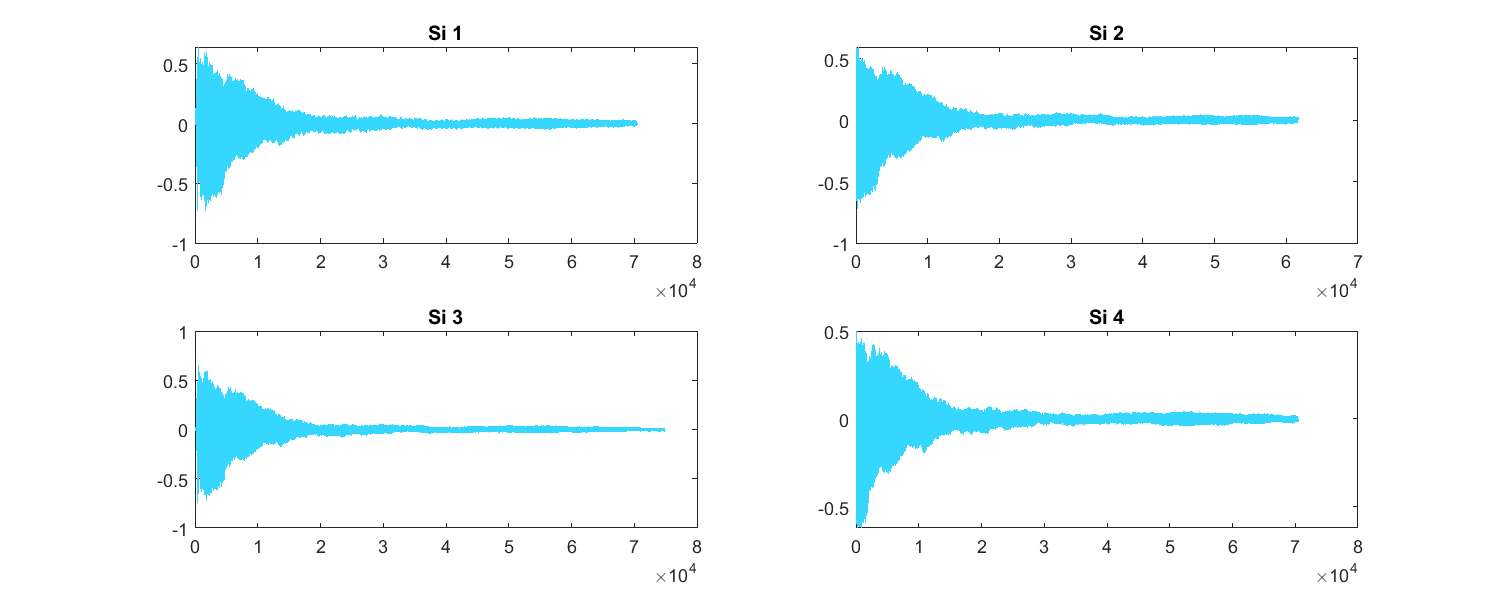

%Cortes de Si
bCut1 = cutWithTime(tArray, signal, 52.4,54);
bCut2 = cutWithTime(tArray, signal,54.6, 56);
bCut3 = cutWithTime(tArray, signal, 56.8, 58.5);
bCut4 = cutWithTime(tArray, signal, 59,60.6 );
f = figure();
f.Position = [100 100 1000 400];
subplot(2,2,1)
plot(bCut1, "Color", "#36d7ff")
title("Si 1")
subplot(2,2,2)
plot(bCut2,"Color" ,"#36d7ff")
title("Si 2")
subplot(2,2,3)
plot(bCut3,"Color" ,"#36d7ff")
title("Si 3")
subplot(2,2,4)
plot(bCut4,"Color" ,"#36d7ff")
title("Si 4")

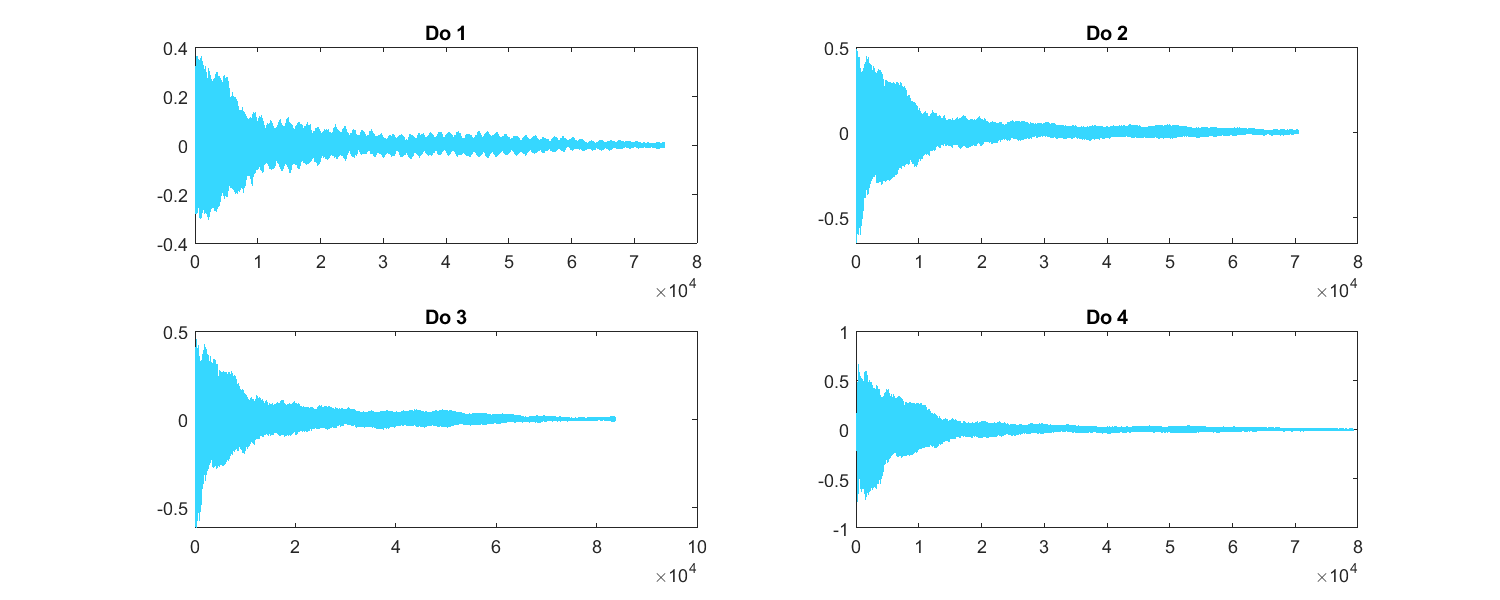

%Cortes del segundo do
c2Cut1 = cutWithTime(tArray, signal,61.3,63);
c2Cut2 = cutWithTime(tArray, signal,63.4, 65);
c2Cut3 = cutWithTime(tArray, signal, 65.6, 67.5);
c2Cut4 = cutWithTime(tArray, signal, 67.7, 69.5);
f = figure();
f.Position = [100 100 1000 400];
subplot(2,2,1)
plot(c2Cut1, "Color", "#36d7ff")
title("Do 1")
subplot(2,2,2)
plot(c2Cut2,"Color" ,"#36d7ff")
title("Do 2")
subplot(2,2,3)
plot(c2Cut3,"Color" ,"#36d7ff")
title("Do 3")
subplot(2,2,4)
plot(c2Cut4,"Color" ,"#36d7ff")
title("Do 4")

### Análisis completo de una de las notas 

La nota de Do central tiene una frecuencia aproximada de 261.63 Hz. Vamos a corroborar que se esté detectando correctamente en el espectrograma, también quisiera aplicar la transformada CWT y visualizar el espectro de Hilbert.

%Espectrogram
windowType = WindowType.BLACKMAN;
windowPoints = 2000;
overlap = 0.5;
spectrogramPlotter = SpectrogramPlotter(windowType,windowPoints, overlap);
subplot()
spectrogramPlotter.plotMagnitudeSpectrogram(cCut1', (0:length(cCut1) - 1)*deltaT);

Descripción 
-----------------
Tipo de ventana: BLACKMAN
Puntos en la ventana: 2000
Porcentaje de traslape: 0.5



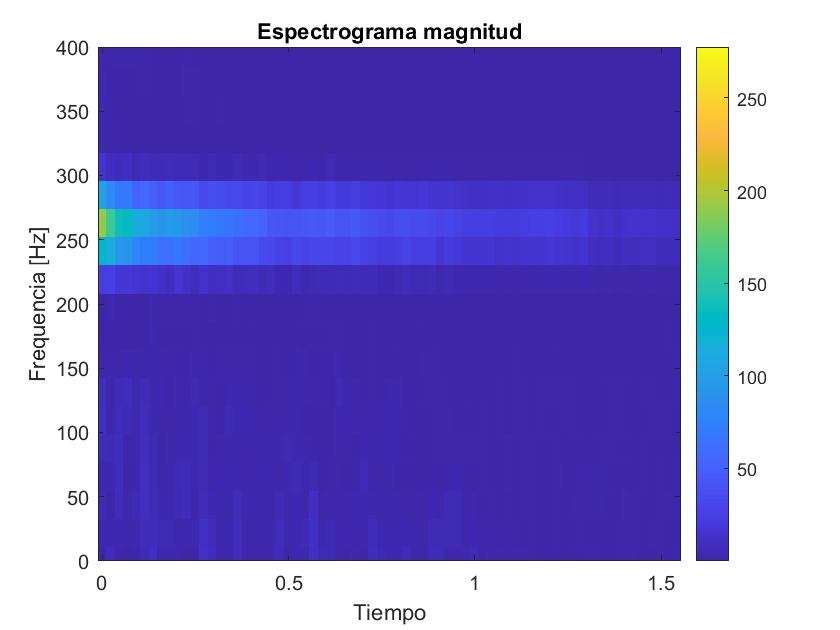

ylim([0,400])


%Escalograma (CWT)

continuousWaveletTransformer = ContinuousWaveletTransform();
minIndexCWT =1;
maxIndexCWT = 3000;

cutTimeCWT = (0:length(cCut1) - 1)*deltaT;
cutTimeCWT = cutTimeCWT(minIndexCWT:maxIndexCWT);
cutSignalCWT = cCut1(minIndexCWT:maxIndexCWT);


[sArray, tArray, correlationMatrix] = continuousWaveletTransformer.computeContinuousTransform(cutSignalCWT', cutTimeCWT', 0.0008, 0.0005, 1000, WaveletType.DAUBECHIES_4);

   1.1102e-16



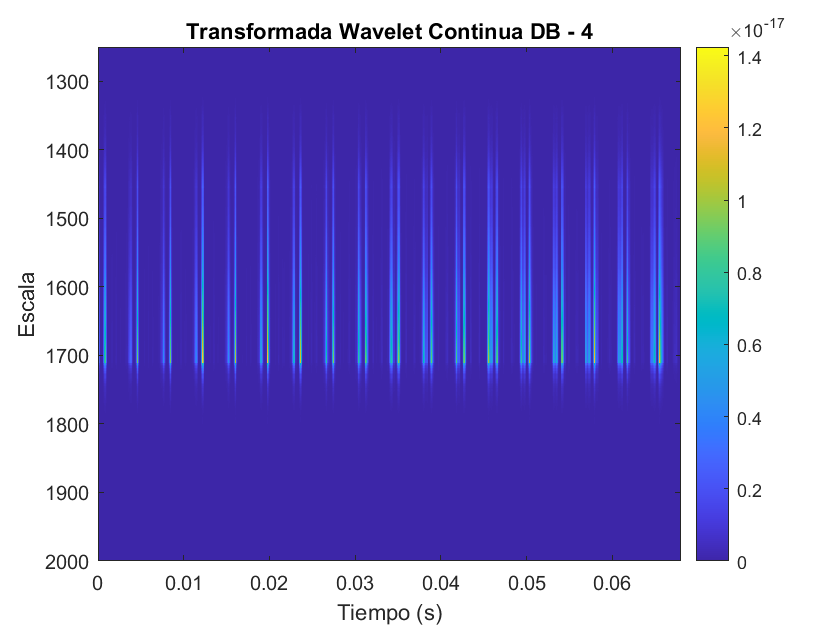

figure()
set(gca,'YDir','normal');
imagesc(tArray, flip(1./sArray), correlationMatrix.^2)
title("Transformada Wavelet Continua DB - 4")
xlabel("Tiempo (s)")
ylabel("Escala")
colorbar

1/(2*pi*261.63)

ans = 6.0832e-04

2*pi*261.63

ans = 1.6439e+03

%Espectro de Hilbert
hilbertTransformer = HilbertHuangTransform();
nLevels = 5;
S = 20;

[frequencies, times, hilbertSpectrum] = hilbertTransformer.getHilbertSpectrumMaxMin(cCut1',nLevels,S, Fs, 100, 10, 300);

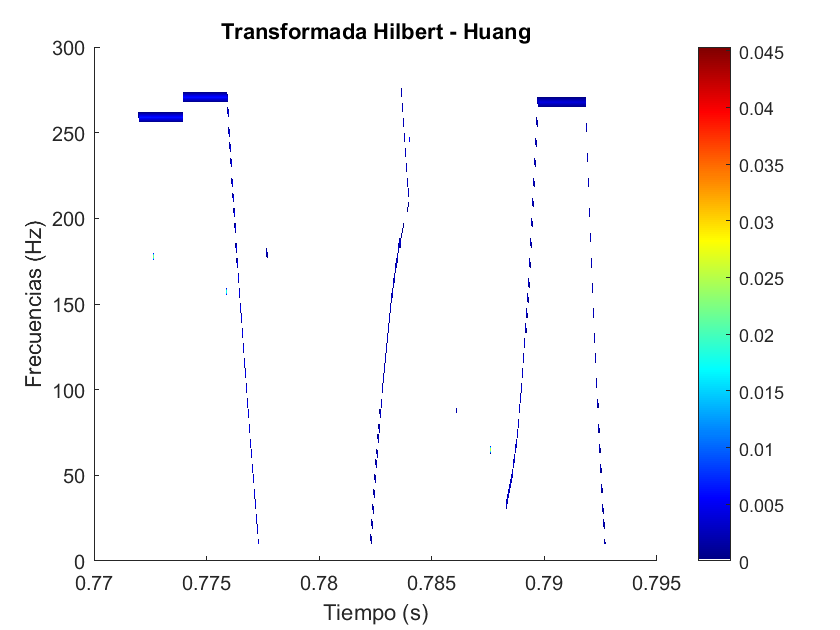

offset = 34000;
maxIndex = 1000;

figure()
hold on 
s = pcolor(times(offset:offset +maxIndex), frequencies, hilbertSpectrum(:, offset:offset + maxIndex));
s.FaceColor = "interp";
s.EdgeColor = "none";
xlabel("Tiempo (s)")
ylabel("Frecuencias (Hz)")
title("Transformada Hilbert - Huang")
myColorMap = jet(256);
myColorMap(1,:) = 1;
colormap(gca,myColorMap);
colorbar
hold off

### Obtención de la base de datos a partir de las señales de entrenamiento

cuts = {cCut1, cCut2, cCut3, cCut4, dCut1, dCut2, dCut3, dCut4, eCut1, eCut2, eCut3, eCut4, fCut1, fCut2, fCut3, fCut4, gCut1, gCut2, gCut3, gCut4, aCut1, aCut2, aCut3, aCut4, bCut1, bCut2, bCut3, bCut4, c2Cut1, c2Cut2, c2Cut3, c2Cut4};
labels = {NoteType.C, NoteType.C, NoteType.C, NoteType.C,NoteType.D, NoteType.D, NoteType.D, NoteType.D, NoteType.E, NoteType.E, NoteType.E, NoteType.E, NoteType.F, NoteType.F, NoteType.F, NoteType.F, NoteType.G, NoteType.G, NoteType.G, NoteType.G, NoteType.A, NoteType.A, NoteType.A, NoteType.A, NoteType.B, NoteType.B, NoteType.B, NoteType.B, NoteType.C2, NoteType.C2, NoteType.C2, NoteType.C2};
%Importamos funciones de descomposición wavelet
addpath("G:\Mi unidad\MCC\Tercer Semestre\Análisis de señales en tiempo frecuencia\Tareas\Construcción Daubechies");
%Importamos transformadad corta rapida
addpath("G:\Mi unidad\MCC\Tercer Semestre\Análisis de señales en tiempo frecuencia\Tareas\STFT");
%Importamos Transformada Hilbert Huang
addpath("G:\Mi unidad\MCC\Tercer Semestre\Análisis de señales en tiempo frecuencia\Tareas\Hilbert_Huang");
featureTable = [];
labelTable = [];
%Tamaño de la ventana en el espectrograma
windowSize = 700;
%Porcentaje de traslape en las ventanas
overlap = 0.5;
%Tipo de ventana
windowType = WindowType.BLACKMAN;
%Tipo de wavelet
waveletType = WaveletType.DAUBECHIES_4;
%Número de detalles Wavelet a extraer
nDetails = 5;

featureExtractor = FeatureTableNoteExtractor(windowSize, overlap, windowType, waveletType);
for i = 1:length(cuts)
    features = featureExtractor.extractFeatures(cuts{i}',Fs, nDetails);
    featureTable = [featureTable; features];
    nVectors = size(features, 1);
    for j = 1:nVectors
        labelTable = [labelTable; uint8(labels{i})];
    end
end

means = mean(featureTable,1);
sds = std(featureTable, 1);

### Preprocesamiento

%Normalización de los datos
dataCooker = DataPrecook();
normalizedFeatures = zeros(size(featureTable, 1), size(featureTable, 2));

for i = 1:size(normalizedFeatures, 2)
    normalizedFeatures(:,i) = dataCooker.normalize(featureTable(:,i));
end
percentageTraining = 0.8;
[trainingData, trainingLabels, validationData, validationLabels] = dataCooker.splitData(normalizedFeatures, labelTable, 1 - percentageTraining);

### Visualización 

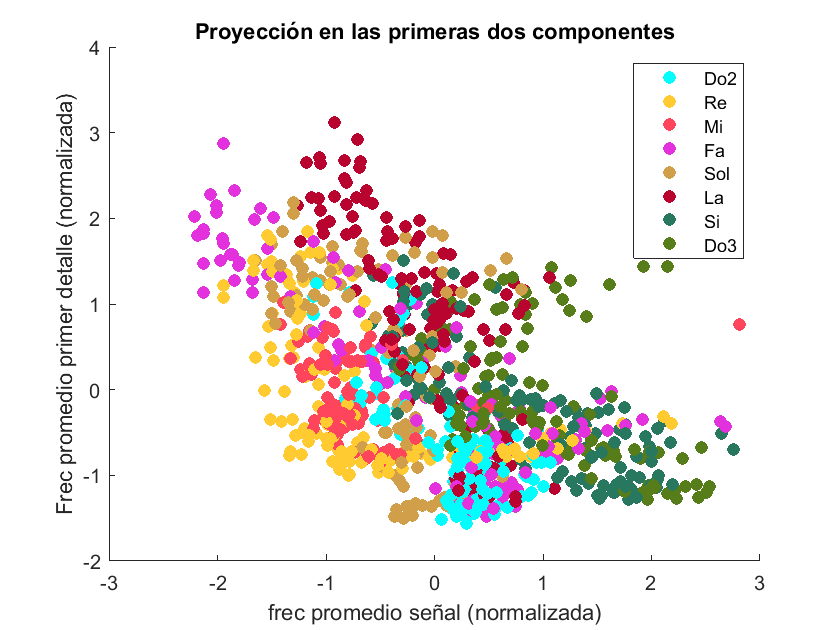

%Aquí para la visualizacón 
%Una pequeña visualización de las dos primeras componentes de los datos

color1 = "#03fcfc";
color2 = "#ffcb30";
color3 = "#ff455b";
color4 = "#e332dd";
color5 = "#d19f49";
color6 = "#b8042e";
color7 = "#287860";
color8 = "#577d1a";

figure();
hold on 
title("Proyección en las primeras dos componentes")
h1 = plot(0,0,'Marker', 'o', 'color', color1, 'DisplayName','Do2', 'MarkerFaceColor',color1, 'LineStyle', 'none');
h2 = plot(0,0,'Marker', 'o', 'color', color2, 'DisplayName','Re','MarkerFaceColor',color2,'LineStyle', 'none');
h3 = plot(0,0,'Marker', 'o', 'color', color3, 'DisplayName','Mi','MarkerFaceColor',color3,'LineStyle', 'none');
h4 = plot(0,0,'Marker', 'o', 'color', color4, 'DisplayName','Fa','MarkerFaceColor',color4,'LineStyle', 'none');
h5 = plot(0,0,'Marker', 'o', 'color', color5, 'DisplayName','Sol','MarkerFaceColor',color5,'LineStyle', 'none');
h6 = plot(0,0,'Marker', 'o', 'color', color6, 'DisplayName','La','MarkerFaceColor',color6,'LineStyle', 'none');
h7 = plot(0,0,'Marker', 'o', 'color', color7, 'DisplayName','Si','MarkerFaceColor',color7,'LineStyle', 'none');
h8 = plot(0,0,'Marker', 'o', 'color', color8, 'DisplayName','Do3','MarkerFaceColor',color8,'LineStyle', 'none');


for i = 1:1000
    point = trainingData(i,:);
    if(trainingLabels(i) == 0)
        plot(point(1), point(2), 'o', 'color', color1,'MarkerFaceColor',color1)
    elseif(trainingLabels(i) == 1)
        plot(point(1), point(2), 'o', 'color', color2,'MarkerFaceColor',color2)
    elseif(trainingLabels(i) == 2)
        plot(point(1), point(2), 'o', 'color', color3,'MarkerFaceColor',color3)
    elseif(trainingLabels(i) == 3)
        plot(point(1), point(2), 'o', 'color', color4,'MarkerFaceColor',color4)
    elseif(trainingLabels(i) == 4)
        plot(point(1), point(2), 'o', 'color', color5,'MarkerFaceColor',color5)
    elseif(trainingLabels(i) == 5)
        plot(point(1), point(2), 'o', 'color', color6,'MarkerFaceColor',color6)
    elseif(trainingLabels(i) == 6)
        plot(point(1), point(2), 'o', 'color', color7,'MarkerFaceColor',color7)
    elseif(trainingLabels(i) == 7)
        plot(point(1), point(2), 'o', 'color', color8,'MarkerFaceColor',color8)
    elseif(trainingLabels(i) == 8)
        plot(point(1), point(2), 'o', 'color', color9,'MarkerFaceColor',color9)
    end
end

xlabel("frec promedio señal (normalizada)")
ylabel("Frec promedio primer detalle (normalizada)")

f = get(gca,'Children');
legend([h1,h2,h3,h4,h5,h6,h7,h8])
hold off

### Entrenamiento del modelo


%Definimos el clasificador
classifier = MultiClassifier(trainingData, trainingLabels, validationData, validationLabels);

%Entrenamos el clasificador 
classifier = classifier.trainSVMClassifier();
disp("Trained");

Trained


### Evaluación del modelo con los datos de validación (para cada nota)

cAccuracy = classifier.computeSVMClassifierAccuracy(0);
disp("cAcc "+string(cAccuracy));

cAcc 0.95756


disp("dAcc "+string(dAccuracy));

dAcc 0.98219


eAccuracy = classifier.computeSVMClassifierAccuracy(2);
disp("eAcc "+string(eAccuracy));

eAcc 0.96905


fAccuracy = classifier.computeSVMClassifierAccuracy(3);
disp("fAcc "+string(eAccuracy));

fAcc 0.96905


gAccuracy = classifier.computeSVMClassifierAccuracy(4);
disp("gAcc "+string(gAccuracy));

gAcc 0.88451


aAccuracy = classifier.computeSVMClassifierAccuracy(5);
disp("aAcc "+string(aAccuracy));

aAcc 0.91316


bAccuracy = classifier.computeSVMClassifierAccuracy(6);
disp("bAcc "+string(bAccuracy));

bAcc 0.875


c2Accuracy = classifier.computeSVMClassifierAccuracy(7);
disp("c2Acc "+string(c2Accuracy));

c2Acc 0.87534


T = table(cAccuracy, dAccuracy, eAccuracy, fAccuracy, gAccuracy, aAccuracy, bAccuracy, c2Accuracy)

T = 1×8 table
    cAccuracy    dAccuracy    eAccuracy    fAccuracy    gAccuracy    aAccuracy    bAccuracy    c2Accuracy
    _________    _________    _________    _________    _________    _________    _________    __________

     0.95756      0.98219      0.96905      0.87927      0.88451      0.91316       0.875       0.87534  


### Prueba con una canción sencilla 

Mary had a little lamb tocada lentamente. 

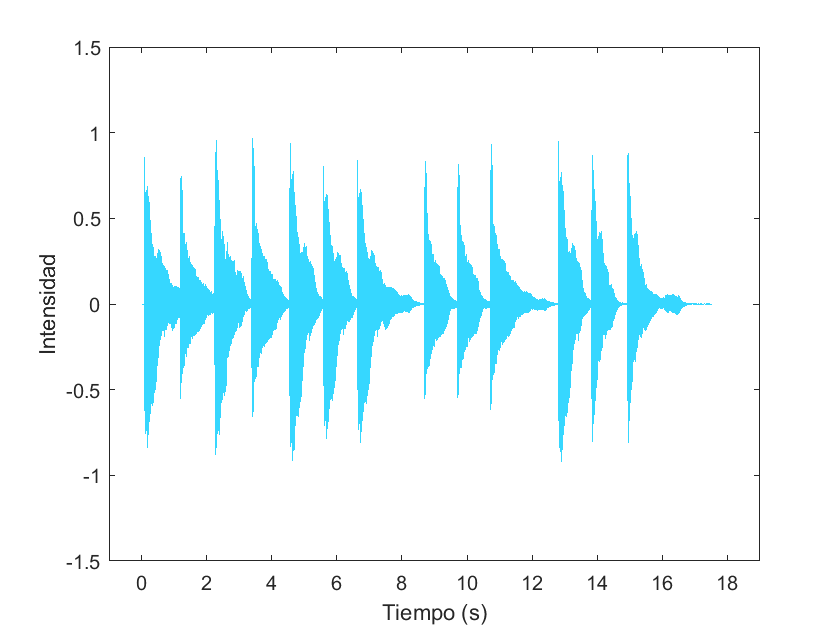

[marySong, FsMary] = audioread("mary_had_a_little_lamb.m4a");
marySong = marySong(:,1);
deltaTMary = 1/FsMary;
tArrayMary = (0:length(marySong) - 1)*deltaTMary;

figure()
plot(tArrayMary, marySong, 'Color', '#36d7ff');
xlabel("Tiempo (s)")
ylabel("Intensidad")
ylim([-1.5, 1.5])
xlim([-1,19])

sound(marySong, FsMary)

tabComputer = TabComputer(classifier, nDetails, windowSize, overlap, windowType, waveletType);
windowSizeTab = 1000;
cuts = [[0.2, 1.1];[1.25, 2];[2.3,3.2];[3.41, 4.4];[4.61, 5.5];[5.65, 6.5];[6.75, 7.8]; [8.77, 9.6]; [9.8,10.5];[10.72, 11.9];[12.9, 13.7]; [13.9,14.6];[14.90, 15.4]];
tab = tabComputer.analyzeSong(cuts, tArrayMary, marySong', FsMary, means, sds)

   -1.0000         0    0.2000
    2.0000    0.2000    1.1000



tab =    -1.0000         0    0.2000
    2.0000    0.2000    1.1000
   -1.0000    1.1000    1.2500
    1.0000    1.2500    2.0000
   -1.0000    2.0000    2.3000
         0    2.3000    3.2000
   -1.0000    3.2000    3.4100
    1.0000    3.4100    4.4000
   -1.0000    4.4000    4.6100
    2.0000    4.6100    5.5000


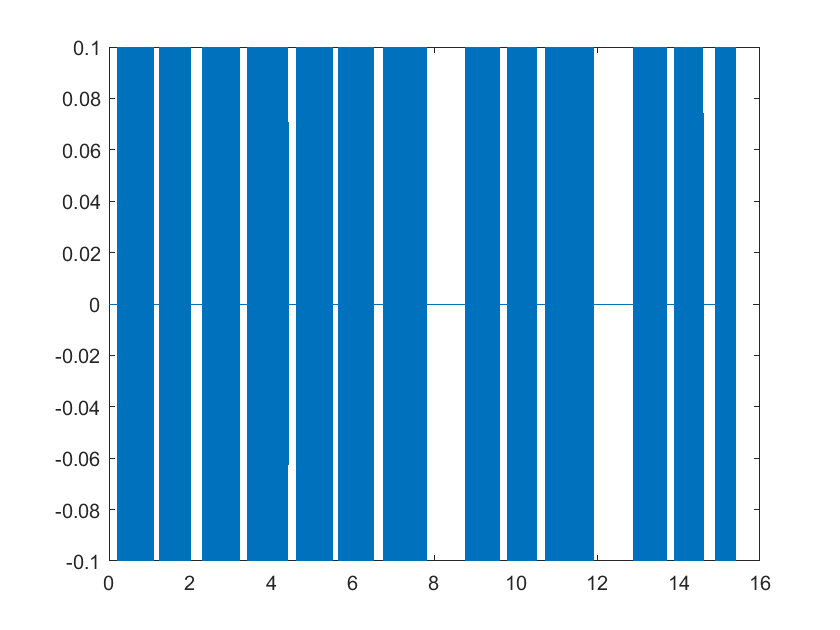

[reconstructedTimes, reconstructedSignal] = tabComputer.playTab(tab, FsMary, 0.1);

figure()
plot(reconstructedTimes, reconstructedSignal)

sound(reconstructedSignal, FsMary)

disp("Secuencia de notas")

Secuencia de notas


notesArray = tab(:,1);
noteSequence = "";
for i = 2:length(tab(:,1))
    noteSequence = noteSequence + string(notesArray(i)) + " ";    
end
disp("Secuencia de notas");

Secuencia de notas


disp(noteSequence);

2 -1 1 -1 0 -1 1 -1 2 -1 2 -1 2 -1 1 -1 1 -1 1 -1 2 -1 4 -1 4 


audiowrite('reconstructed.wav', reconstructedSignal, FsMary)